# Gun Violence in The United States		

## Intro				

Gun violence is a significant and ongoing issue in the United States of America. In 2019, According to data %from the Centers for Disease Control and Prevention, there were over 39,000 deaths that involved a gun or firearm in the U.S. There was also a total of 69,000 people suffering nonfatal gunshot injuries. In the past couple of years, mass shootings (incidents in which four or more people are shot) have become getting increasingly common in recent years and some super serious incidents spark national debates over gun control policies. The availability and ease of obtaining guns and firearms in the U.S. have been cited as contributing factors to the country's high rate of gun violence. We decided to center our project on proving this statement. We want to observe how extreme the correlation of gun violence to ownership of firearms is and hope to %shed light on the importance for stricter gun control measures to address the problem. 

For our csv file, we found a kaggle article that contains a record of over 260,000 gun violence incidents in the US between January 2013 and March 2018. This article had the aim of researching gun violence and making informed predictions about future trends. The data was downloaded from the Gun Violence Archive, a not-for-profit organization that collects and disseminates information about gun-related violence in the US. Due to limitations in the organization's database and functionality, the data was obtained using web scraping %techniques in three stages: querying and scraping incident data for each date, augmenting the data with %additional information, and merging the data into a single CSV file sorted by date. The dataset is available in CSV format, and the project's creator hopes it will inspire researchers to explore and analyze the data. Possibly even using it to build a machine learning system that can detect warning signs of gun violence.  

%Import the Data
gv_data = table2struct(readtable('gunviolence.csv', 'PreserveVariableNames', true));
registry = table2struct(readtable('data.csv', 'PreserveVariableNames', true));
oc = table2struct(readtable('data (1).csv', 'PreserveVariableNames', true));
%Scrub the Data
 
%Remove unnescassary fields
fieldsToRemove = {'date', 'incident_id', 'city_or_county','address','incident_url',...
    'source_url','incident_url_fields_missing', 'congressional_district',...
    'gun_stolen', 'gun_type', 'incident_characteristics', 'latitude', ...
    'location_description', 'longitude', 'n_guns_involved', 'notes', ...
    'participant_age', 'participant_age_group', 'participant_gender', 'participant_name',...
    'participant_relationship', 'participant_status', 'participant_type', ...
    'sources', 'state_house_district', 'state_senate_district'};

for i = 1:length(fieldsToRemove)
    gv_data = rmfield(gv_data, fieldsToRemove{i});
end
high_states = ["Wyoming", "West Virginia", "Montana", "Idaho", "Alaska", "South Dakota"];
low_states = ["Massachusetts", "Hawaii", "New Jersey", "Rhode Island", "New York", "Calfornia"];


x = [];
for i = 1:length(gv_data)
    states = string(gv_data(i).state);
    for j = 1:length(high_states)
        if strcmp(high_states(j), states)
            x = [x states];
        end 
    end
end
y = [];

for i = 1:length(gv_data)
    states = string(gv_data(i).state);
    for j = 1:length(low_states)
        if strcmp(low_states(j), states)
            y = [y states];
        end
    end
end

%the states with the three highest gun ownership rates
wyomingvictims = 0;
west_virginiavictims = 0;
montanavictims = 0;
IDvictims = 0;
ALvictims = 0;
SDvictims = 0;
%the states with the three lowest gun ownership rates
massvictims = 0;
HIvictims = 0;
new_jerseyvictims = 0;
RIvictims = 0;
NYvictims = 0;
CAvictims = 0;
%we decided to use these states to gather samples from both the high and
%low end of gun ownership. That way, if there is a correlation, it will
%clearly show
%for each state we found the total number of people both killed an injured
for i = 1:length(gv_data)
    if string(gv_data(i).state) == "Wyoming"
        z1 = gv_data(i).n_injured + gv_data(i).n_killed;
        wyomingvictims = wyomingvictims + z1;
    end 
end
disp(wyomingvictims)

   125




for i = 1:length(gv_data)
    if string(gv_data(i).state) == "West Virginia"
        z2 = gv_data(i).n_injured + gv_data(i).n_killed;
        west_virginiavictims = west_virginiavictims + z2;
    end 
end
disp(west_virginiavictims)

   984





for i = 1:length(gv_data)
    if string(gv_data(i).state) == "Montana"
        z3 = gv_data(i).n_injured + gv_data(i).n_killed;
        montanavictims = montanavictims + z3;
    end 
end
disp(montanavictims)

   290




for i = 1:length(gv_data)
    if string(gv_data(i).state) == "Idaho"
        z4 = gv_data(i).n_injured + gv_data(i).n_killed;
        IDvictims = IDvictims + z4;
    end 
end

for i = 1:length(gv_data)
    if string(gv_data(i).state) == "Alaska"
        z5 = gv_data(i).n_injured + gv_data(i).n_killed;
        ALvictims = ALvictims + z5;
    end 
end
for i = 1:length(gv_data)
    if string(gv_data(i).state) == "South Dakota"
        z6 = gv_data(i).n_injured + gv_data(i).n_killed;
        SDvictims = SDvictims + z6;
    end 
end


for i = 1:length(gv_data)
    if string(gv_data(i).state) == "Massachusetts"

z7 = gv_data(i).n_injured + gv_data(i).n_killed;
        massvictims = massvictims + z7;
    end 
end
disp(massvictims)

        2173






for i = 1:length(gv_data)
    if string(gv_data(i).state) == "Hawaii"
        z8 = gv_data(i).n_injured + gv_data(i).n_killed;
        HIvictims = HIvictims + z8;
    end 
end
disp(HIvictims)

   148




for i = 1:length(gv_data)
    if string(gv_data(i).state) == "New Jersey"
        z9 = gv_data(i).n_injured + gv_data(i).n_killed;
        new_jerseyvictims = new_jerseyvictims + z9;
    end 
end
disp(new_jerseyvictims)

        3708




for i = 1:length(gv_data)
    if string(gv_data(i).state) == "Rhode Island"
        z10 = gv_data(i).n_injured + gv_data(i).n_killed;
        RIvictims = RIvictims + z10;
    end 
end

for i = 1:length(gv_data)
    if string(gv_data(i).state) == "New York"
        z11 = gv_data(i).n_injured + gv_data(i).n_killed;
        NYvictims = NYvictims + z11;
    end 
end

for i = 1:length(gv_data)
    if string(gv_data(i).state) == "California"
        z12 = gv_data(i).n_injured + gv_data(i).n_killed;
        CAvictims = CAvictims + z12;
    end 
end



%divide each of the victim count by the population of each state in order
%to account for varying sizes in population
high_states_victimsbypop = [wyomingvictims/580817, west_virginiavictims/1775932, montanavictims/1112668,IDvictims/2135024, ALvictims/1395847, SDvictims/8820504];
noc_states_victimsbypop = [massvictims/7174604, HIvictims/1483762, new_jerseyvictims/9438124, RIvictims/1110822, NYvictims/20448194, CAvictims/40223504];
high_states_victims = [wyomingvictims, west_virginiavictims, montanavictims, IDvictims, ALvictims, SDvictims];
low_states_victims = [massvictims, HIvictims, new_jerseyvictims, RIvictims, NYvictims, CAvictims];
avg_highvictims = mean(high_states_victims)

avg_highvictims = 418.3333

avg_lowvictims = mean(low_states_victims)

avg_lowvictims = 4.4013e+03

avg_vict = [avg_lowvictims avg_highvictims];
% put all the victims from everything in this vector
%then create a bar graph of each of these values
bar(avg_vict);
title("average injured or killed");
set(gca,'xticklabel',{'Low gun ownership','High gun ownership'})
ylabel("Killed and Injured")


bar(high_states_victims);
title("high ownership rates victims");
ylabel("Number injured or killed by population")
set(gca,'xticklabel',{'Wyoming','West Virginia', 'Montana', 'Idaho', 'Alaska', 'South Dakota'})


bar(low_states_victims);
title("low ownership rates victims");
ylabel("victims by population")
set(gca,'xticklabel',{'Massachusetts','Hawaii', 'New Jersey', 'Rhode Island', 'New York', 'California'})


%assign gun ownership rates to states
for i = 1:length(registry)
    if registry(i).state == "Wyoming"
        wyomingor = registry(i).gunOwnership ;
    elseif registry(i).state == "West Virginia"
        west_virginiaor = registry(i).gunOwnership ;
    elseif registry(i).state == "Montana"
        montanaor = registry(i).gunOwnership ;
    elseif registry(i).state == "Idaho"
        IDor = registry(i).gunOwnership ;
    elseif registry(i).state == "Alaska"
        ALor = registry(i).gunOwnership ;
    elseif registry(i).state == "South Dakota"
        SDor = registry(i).gunOwnership ;
    elseif registry(i).state == "Massachusetts"
        massor = registry(i).gunOwnership ;
    elseif registry(i).state == "Hawaii"
        HIor = registry(i).gunOwnership ;
    elseif registry(i).state == "New Jersey"
        new_jerseyor = registry(i).gunOwnership ;

    elseif registry(i).state == "Rhode Island"
        RIor = registry(i).gunOwnership ;
    elseif registry(i).state == "New York"
        NYor = registry(i).gunOwnership ;
    elseif registry(i).state == "California"
        CAor = registry(i).gunOwnership ;
    end 
end



ownershiprates = [wyomingor, west_virginiaor,montanaor, IDor, ALor, SDor, massor,HIor, new_jerseyor, RIor, NYor, CAor]';
victims_bypop = [high_states_victimsbypop noc_states_victimsbypop]';
table(victims_bypop, ownershiprates)

ans = 12×2 table
    victims_bypop    ownershiprates
    _____________    ______________

     0.00021521          0.662     
     0.00055408          0.585     
     0.00026063          0.663     
     0.00014754          0.601     
     0.00042412          0.645     
     2.3128e-05          0.553     
     0.00030287          0.147     
     9.9746e-05          0.149     
     0.00039287          0.147     
      0.0003682          0.148     
     0.00033079          0.199     
     0.00032832          0.283     


c = corrcoef(ownershiprates, victims_bypop)

c =     1.0000   -0.0760
   -0.0760    1.0000


coeffs = polyfit(ownershiprates, victims_bypop, 1);
x_fit = linspace(min(ownershiprates), max(ownershiprates), 100);
y_fit = polyval(coeffs, x_fit);
plot(ownershiprates, victims_bypop, 'k*', x_fit, y_fit)
title(c(2))

ylabel("Number Injured or Killed by population")
xlabel("ownership rates")

%we plotted this assuming that there would be a positive correlation 


%input the total number of guns of the same states you had as before


%plot these against the deaths by population
for i = 1:length(registry)
    if registry(i).state == "Wyoming"
        wyomingRR = registry(i).totalGuns ;
    elseif registry(i).state == "West Virginia"
        west_virginiaRR = registry(i).totalGuns ;
    elseif registry(i).state == "Montana"
        montanaRR = registry(i).totalGuns;
    elseif registry(i).state == "Idaho"
        IDRR = registry(i).totalGuns ;
    elseif registry(i).state == "Alaska"
        ALRR = registry(i).totalGuns ;
    elseif registry(i).state == "South Dakota"
        SDRR = registry(i).totalGuns ;
    elseif registry(i).state == "Massachusetts"
        massRR = registry(i).totalGuns ;
    elseif registry(i).state == "Hawaii"
        HIRR = registry(i).totalGuns ;
    elseif registry(i).state == "New Jersey"
        new_jerseyRR = registry(i).totalGuns ;

    elseif registry(i).state == "Rhode Island"
        RIRR = registry(i).totalGuns ;
    elseif registry(i).state == "New York"
        NYRR = registry(i).totalGuns ;
    elseif registry(i).state == "California"
        CARR = registry(i).totalGuns ;
    end 
end
%this plotwas meant to measure the correlation between the number of guns
%in each state and the number of people killed and injured
totalguns = [wyomingRR, west_virginiaRR, montanaRR, IDRR, ALRR, SDRR, massRR, HIRR, new_jerseyRR, RIRR, NYRR, CARR];

c2 = corrcoef(totalguns, victims_bypop)

c2 =     1.0000    0.0771
    0.0771    1.0000


coeffs = polyfit(totalguns, victims_bypop, 1);
x_fit = linspace(min(totalguns), max(totalguns), 100);
y_fit = polyval(coeffs, x_fit);
plot(totalguns, victims_bypop, 'k*', x_fit, y_fit)
title(c2(2))
xlabel('total number of guns per state')
ylabel('victims by population')

%this for loop assigns each state a code, 1, -1 or 0 depending on whether
%it is an open carry, non open carry or state with another policy
%this loop also places the number of killed and injured within each state
%into a vector depending on which code it was assigned
%we used this data to plot by state policy and observe any correlation on
%that front
oc_states = [];
noc_states = [];
other = [];
other_victims = [];
noc_victs = [];
oc_victs = [];
for i = 1:length(oc)
    if string(oc(i).state) == "Wyoming"
        if string(oc(i).openCarryHandgun) == "Allowed"
            wyomingoc = 1
            oc_states = [oc_states wyomingvictims];
            oc_victs = [oc_victs victims_bypop(1)];
        elseif string(oc(i).openCarryHandgun) == "Prohibited"
            wyomingoc = -1
            noc_states = [noc_states wyomingvictims];
            noc_victs = [noc_victs victims_bypop(1)];
        else
            wyomingoc = 0
            other = [other wyomingvictims];
            other_victims = [other_victims victims_bypop(1)];
        end
    elseif string(oc(i).state) == "West Virginia"
        if string(oc(i).openCarryHandgun) == "Allowed"
            WVoc = 1
            oc_states = [oc_states west_virginiavictims];
            oc_victs = [oc_victs victims_bypop(2)];
        elseif string(oc(i).openCarryHandgun) == "Prohibited"
            WVoc = -1
            noc_states = [noc_states west_virginiavictims];
            noc_victs = [noc_victs victims_bypop(2)];
        else
            WVoc = 0
            other = [other west_virginiavictims];
            other_victims = [other_victims victims_bypop(2)];
        end
    elseif string(oc(i).state) == "Montana"
        if string(oc(i).openCarryHandgun) == "Allowed"
            MOoc = 1
            oc_states = [oc_states montanavictims];
            oc_victs = [oc_victs victims_bypop(3)];
        elseif string(oc(i).openCarryHandgun) == "Prohibited"
            MOoc = -1
            noc_states = [noc_states montanavictims];
            noc_victs = [noc_victs victims_bypop(3)];
        else
            MOoc = 0
            other = [other montanavictims];
            other_victims = [other_victims victims_bypop(3)];
        end
    elseif string(oc(i).state) == "Idaho"
        if string(oc(i).openCarryHandgun) == "Allowed"
            IDoc = 1
            oc_states = [oc_states IDvictims];
            oc_victs = [oc_victs victims_bypop(4)];
        elseif string(oc(i).openCarryHandgun) == "Prohibited"
            IDoc = -1
            noc_states = [noc_states IDvictims];
            noc_victs = [noc_victs victims_bypop(4)];
        else
            IDoc = 0
            other = [other IDvictims];
            other_victims = [other_victims victims_bypop(4)];
        end
    elseif string(oc(i).state) == "Alaska"
        if string(oc(i).openCarryHandgun) == "Allowed"
            ALoc = 1
            oc_states = [oc_states ALvictims];
            oc_victs = [oc_victs victims_bypop(5)];
        elseif string(oc(i).openCarryHandgun) == "Prohibited"
            ALoc = -1
            noc_states = [noc_states ALvictims];
            noc_victs = [noc_victs victims_bypop(5)];
        else
            ALoc = 0
            other = [other ALvictims];
            other_victims = [other_victims victims_bypop(5)];
        end
    elseif string(oc(i).state) == "South Dakota"
        if string(oc(i).openCarryHandgun) == "Allowed"
            SDoc = 1
            oc_states = [oc_states SDvictims];
            oc_victs = [oc_victs victims_bypop(6)];
        elseif string(oc(i).openCarryHandgun) == "Prohibited"
            SDoc = -1
            noc_states = [noc_states SDvictims];
            noc_victs = [noc_victs victims_bypop(6)];
        else
            SDoc = 0
            other = [other SDvictims];
            other_victims = [other_victims victims_bypop(6)];
        end
    elseif string(oc(i).state) == "Massachusetts"
        if string(oc(i).openCarryHandgun) == "Allowed"
            MAoc = 1
            oc_states = [oc_states massvictims];
            oc_victs = [oc_victs victims_bypop(7)];
        elseif string(oc(i).openCarryHandgun) == "Prohibited"
            MAoc = -1
            noc_states = [noc_states massvictims];
            noc_victs = [noc_victs victims_bypop(7)];
        else
            MAoc = 0
            other = [other massvictims];
            other_victims = [other_victims victims_bypop(7)];
        end
    elseif string(oc(i).state) == "Hawaii"
        if string(oc(i).openCarryHandgun) == "Allowed"
            HIoc = 1
            oc_states = [oc_states HIvictims];
            oc_victs = [oc_victs victims_bypop(8)];
        elseif string(oc(i).openCarryHandgun) == "Prohibited"
            HIoc = -1
            noc_states = [noc_states HIvictims];
            noc_victs = [noc_victs victims_bypop(8)];
        else
            HIoc = 0
            other = [other HIvictims];
            other_victims = [other_victims victims_bypop(8)];
        end
   elseif string(oc(i).state) == "New Jersey"
        if string(oc(i).openCarryHandgun) == "Allowed"
            NJoc = 1
            oc_states = [oc_states new_jerseyvictims];
            oc_victs = [oc_victs victims_bypop(9)];
        elseif string(oc(i).openCarryHandgun) == "Prohibited"
            NJoc = -1
            noc_states = [noc_states new_jerseyvictims];
            noc_victs = [noc_victs victims_bypop(9)];
        else
            NJoc = 0
            other = [other new_jerseyvictims];
            other_victims = [other_victims victims_bypop(9)];
        end
    elseif string(oc(i).state) == "Rhode Island"
        if string(oc(i).openCarryHandgun) == "Allowed"
            RIoc = 1
            oc_states = [oc_states RIvictims];
            oc_victs = [oc_victs victims_bypop(10)];
        elseif string(oc(i).openCarryHandgun) == "Prohibited"
            RIoc = -1
            noc_states = [noc_states RIvictims];
            noc_victs = [noc_victs victims_bypop(10)];
        else
            RIoc = 0
            other = [other RIvictims];
            other_victims = [other_victims victims_bypop(10)];
        end
   elseif string(oc(i).state) == "New York"
        if string(oc(i).openCarryHandgun) == "Allowed"
            NYoc = 1
            oc_states = [oc_states NYvictims];
            oc_victs = [oc_victs victims_bypop(11)];
        elseif string(oc(i).openCarryHandgun) == "Prohibited"
            NYoc = -1
            noc_states = [noc_states NYvictims];
            noc_victs = [noc_victs victims_bypop(11)];
        else
            NYoc = 0
            other = [other NYvictims];
            other_victims = [other_victims victims_bypop(11)];
        end
    elseif string(oc(i).state) == "California"
        if string(oc(i).openCarryHandgun) == "Allowed"
            CAoc = 1
            oc_states = [oc_states CAvictims];
            oc_victs = [oc_victs victims_bypop(12)];
        elseif string(oc(i).openCarryHandgun) == "Prohibited"
            CAoc = -1
            noc_states = [noc_states CAvictims];
            noc_victs = [noc_victs victims_bypop(12)];
        else
            CAoc = 0
            other = [other CAvictims];
            other_victims = [other_victims victims_bypop(12)];
        end
    end
end

ALoc = 1

CAoc = -1

HIoc = 0

IDoc = 1

MAoc = 0

MOoc = 1

NJoc = 0

NYoc = -1

RIoc = 0

SDoc = 1

WVoc = 1

wyomingoc = 1



bar(noc_states)
title(sprintf("non open carry state victims total: %d",sum(noc_victs)))
ylabel("Killed and Injured by population")
set(gca,'xticklabel',{'New York','California'})

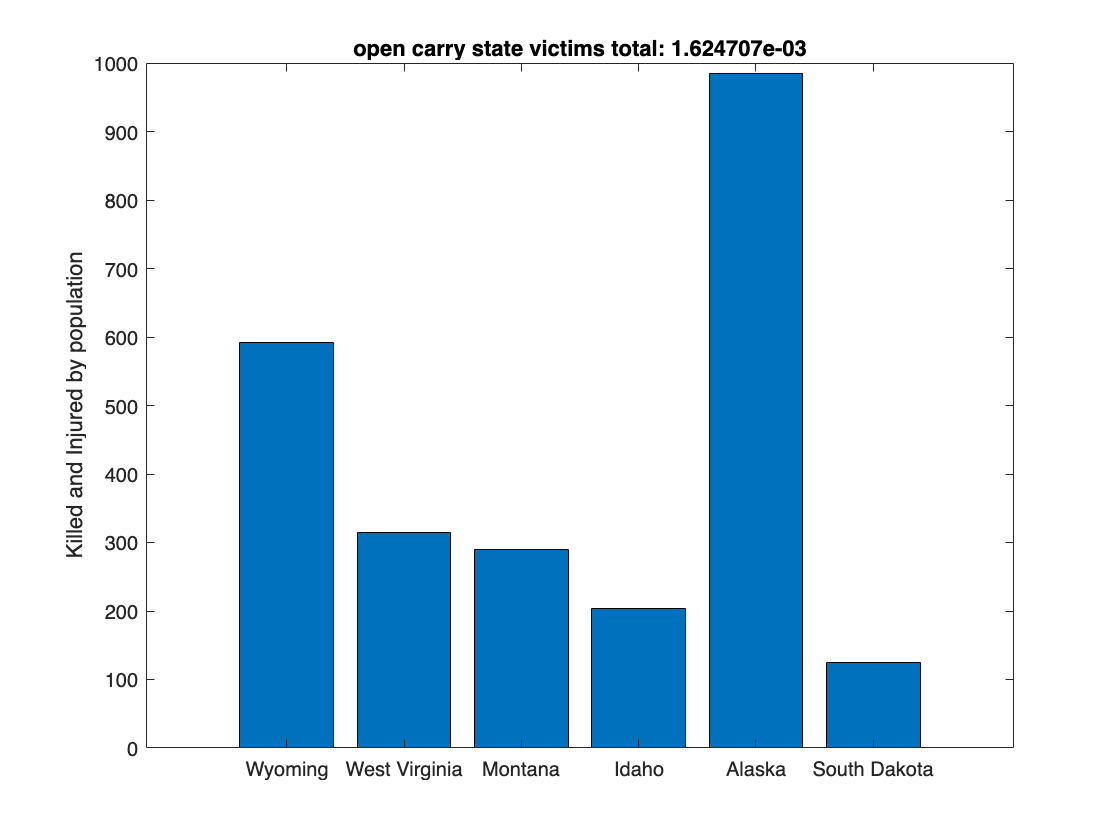


bar(oc_states)
title(sprintf("open carry state victims total: %d", sum(oc_victs)))
ylabel("Killed and Injured by population")
set(gca,'xticklabel',{'Wyoming','West Virginia', 'Montana', 'Idaho', 'Alaska', 'South Dakota'})

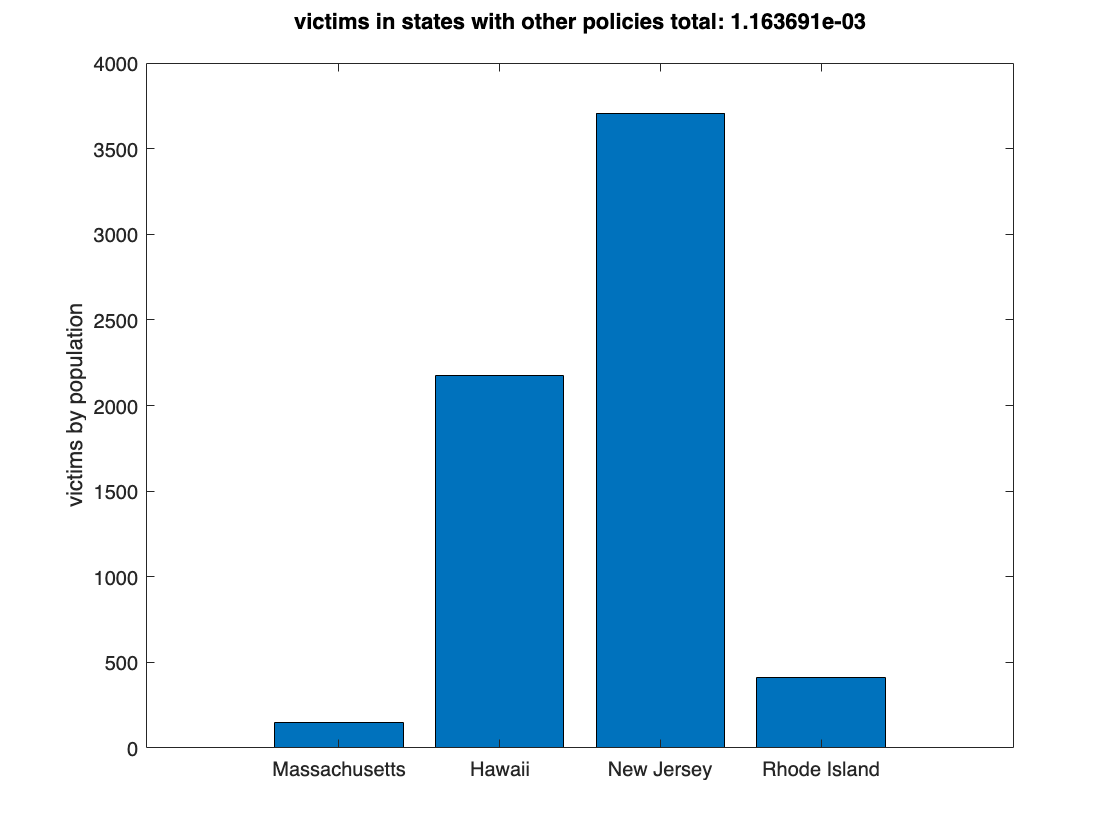


bar(other)
ylabel("victims by population")
set(gca,'xticklabel',{'Massachusetts', 'Hawaii','New Jersey', 'Rhode Island' })
title(sprintf("victims in states with other policies total: %d\n", sum(other_victims)))

oc_own = [ownershiprates(1:6)]';

noc_own = [ownershiprates(11:12)]

noc_own =     0.1990
    0.2830


other_own = [ownershiprates(7) ownershiprates(8) ownershiprates(9), ownershiprates(10)]

other_own =     0.1470    0.1490    0.1470    0.1480


disp(other_victims)

   1.0e-03 *

    0.0997    0.3029    0.3929    0.3682




coeffs = polyfit(oc_own, oc_victs, 1)

coeffs =     0.0025   -0.0013


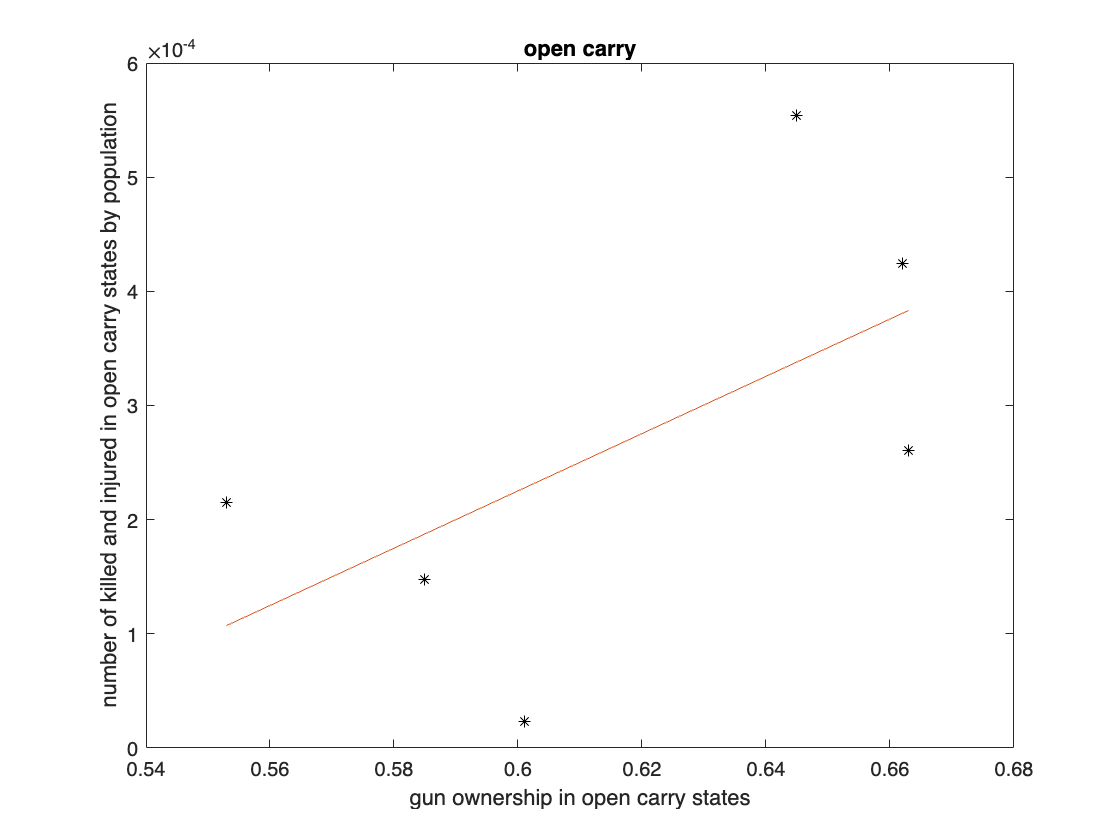

x_fit = linspace(min(oc_own), max(oc_own), 100);
y_fit = polyval(coeffs, x_fit);
plot(oc_own, oc_victs, 'k*', x_fit, y_fit)
title('open carry')
xlabel("gun ownership in open carry states")
ylabel("number of killed and injured in open carry states by population")



coeffs = polyfit(noc_own, noc_victs, 1)

coeffs = 1.0e-03 *

    0.0294    0.3225


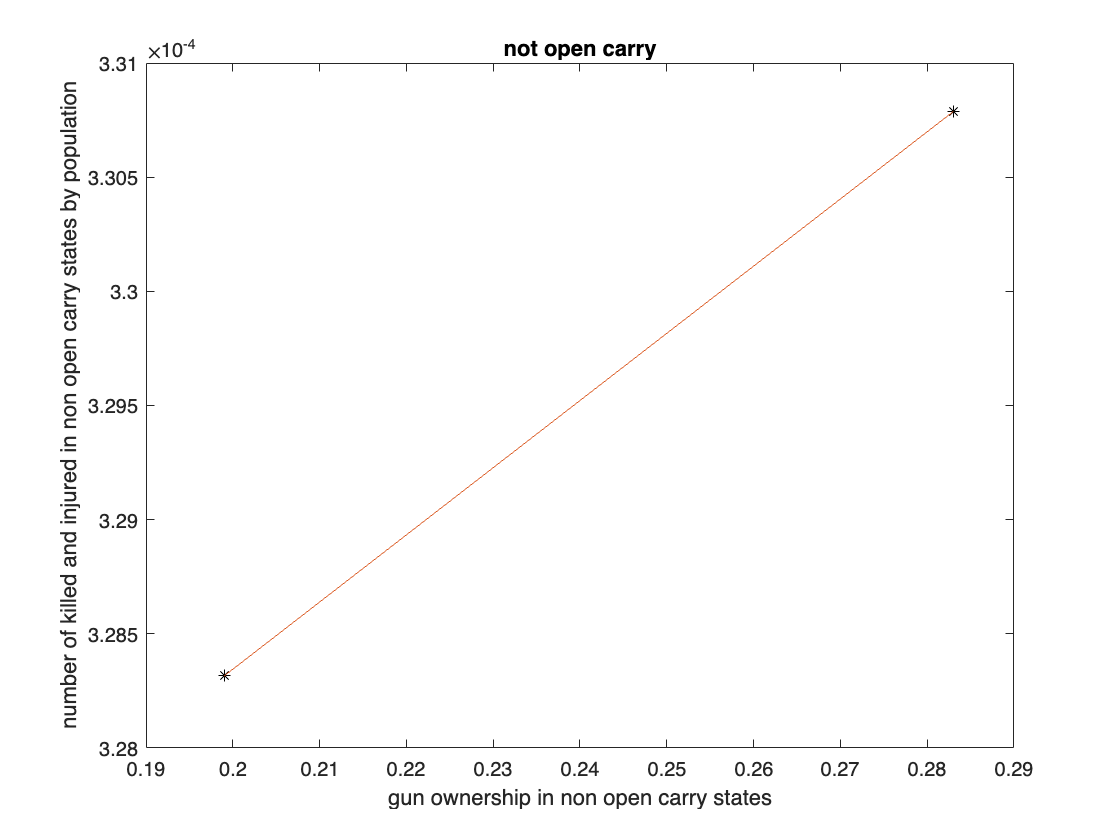

x_fit = linspace(min(noc_own), max(noc_own), 100);
y_fit = polyval(coeffs, x_fit);
plot(noc_own, noc_victs, 'k*', x_fit, y_fit)
title('not open carry')
xlabel("gun ownership in non open carry states")
ylabel("number of killed and injured in non open carry states by population")



coeffs = polyfit(other_own, other_victims, 1)

coeffs =     0.0368   -0.0051


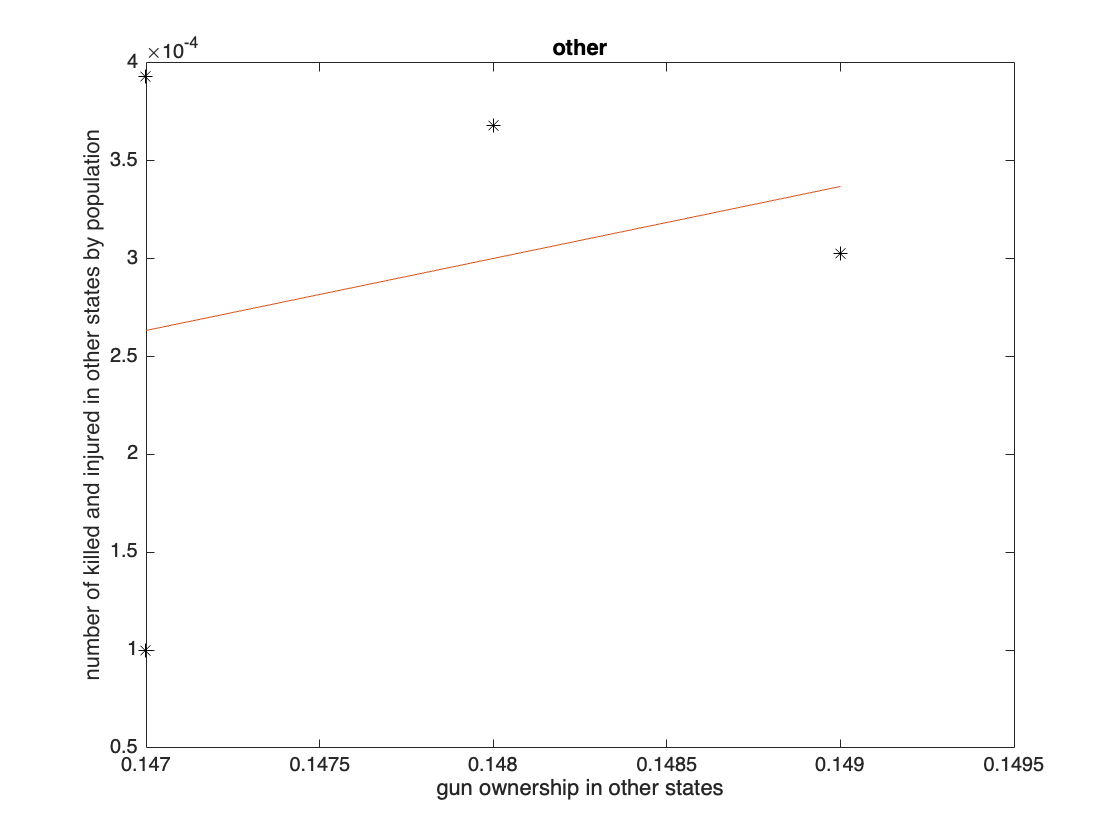

x_fit = linspace(min(other_own), max(other_own), 100);
y_fit = polyval(coeffs, x_fit);
plot(other_own, other_victims, 'k*', x_fit, y_fit)
title('other')
xlabel("gun ownership in other states")
ylabel("number of killed and injured in other states by population")

## ML Graphic

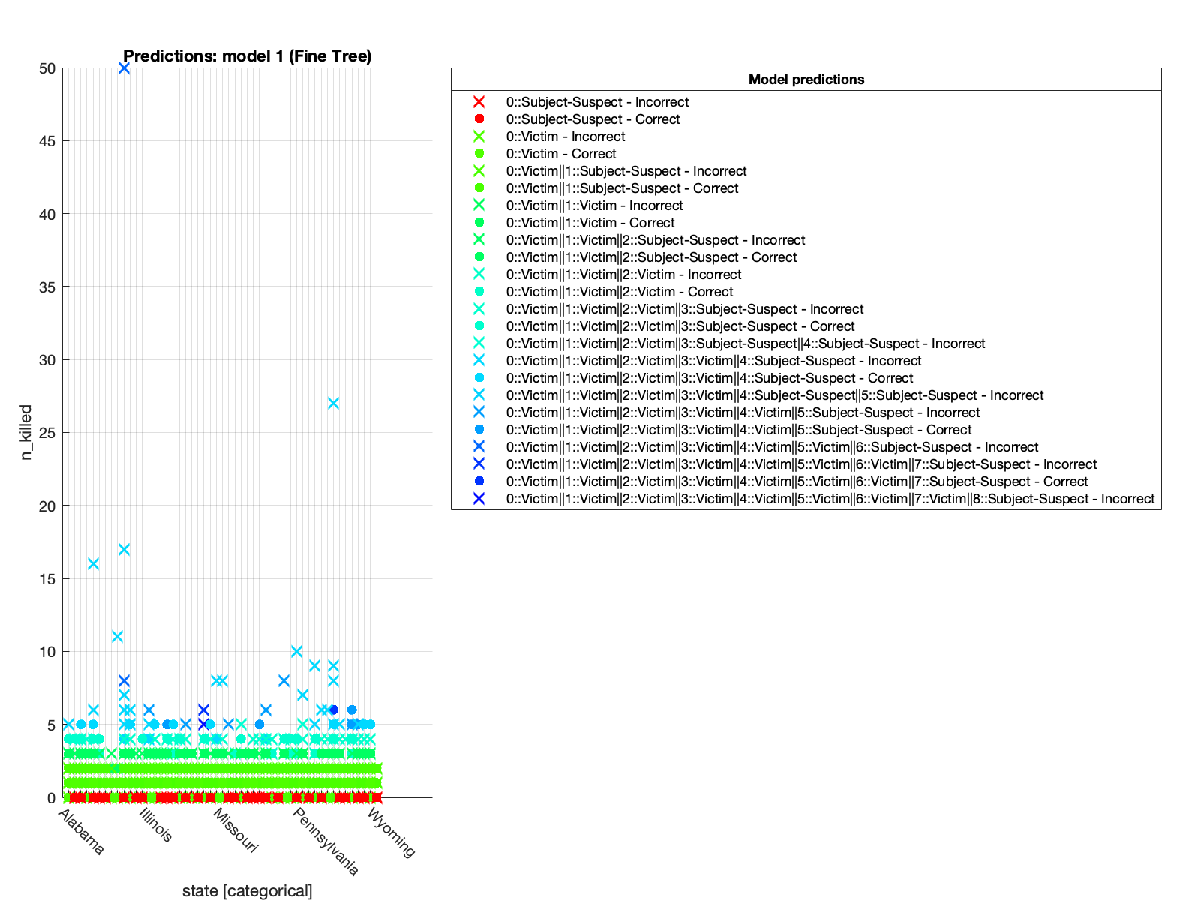The following graph displays the occurrences of shootings in a scatterplot. While only a number of states are shown in the x axis, each column represents a different state organized in alphabetical order. The spots that are marked with an "X" are datapoints which the ML algorithm had determined as potential incorrect values. In this case, these datapoints may have skewed the data, leading the the result we ultimately ended up with.

## Conclusion

        In the first portion of the experiment, we decided that the population density of each city would greatly impact the number of people in killed or injured in shootings. Because of this, we decided to take the sum of the total number of people injured or killed in all instances for each city over the course of the 5 years and divide it by the population of that city. We also decided to pick the top 6 states with the highest gun ownership rates and the 6 states with the lowest gun ownership rates and analyze these 12 states for the rest of the experiment to condense our analysis. We decided this would be the best course of action as it takes a sample from both the high and low end of the data, meaning that any correlation that should exist could be obtained from plotting the two extremes. We then plotted these results against the gun ownership rates of each city. We concluded that this had almost no correlation as the correlation coefficient was -0.075, indicating that there was 1.) a negative correlation that was 2.) rather insignificant. 

        By plotting the average number of people killed and injured per instance in each city, we were able to determine that the average number of people killed in cities with lower gun ownership rates were in fact significantly higher than those in states with high gun ownership rates.

        According to the later half of the analysis, we concluded that there is in fact a slight correlation between the total number of handguns in each state and the number of people killed or injured in shootings per population. From our correlation coefficient of 0.07714, we could conclude that as the number of small firearms in each state increased the rate of victims by population also generally increased. We then decided to separate the states we tested by policy into whether their small firearm open carry policy was “Allowed”, “Permit Required”, or “Prohibited”. We did this in order to try and see if the policy affects the correlation at all. Even though the “Prohibited” had a much higher positive correlation then “Allowed” we still weren’t fully able to conclude that the policy affected the correlation as the sample size for “Prohibited” was much smaller. 

        Because the majority of our data produced null results, we had to research factors that may have resulted in this null hypothesis. One major factor could have been the population density of these states and the number of events held in them each year. Massachusetts, for example, has a stricter firearm policy than many other states, produced much higher numbers of people killed and injured over this time interval. This could be due to large scale events such as the Boston Marathon, which have historically been targets for mass shootings and similar tragedies.

## Works Cited 

Ko, James. *Gun Violence Data *15 Apr. 2018, https://www.kaggle.com/datasets/jameslko/gun-violence-data. 

*Gun Ownership by State 2023*, https://worldpopulationreview.com/state-rankings/gun-ownership-by-state. 

*Open Carry States 2023*, https://worldpopulationreview.com/state-rankings/open-carry-states. 